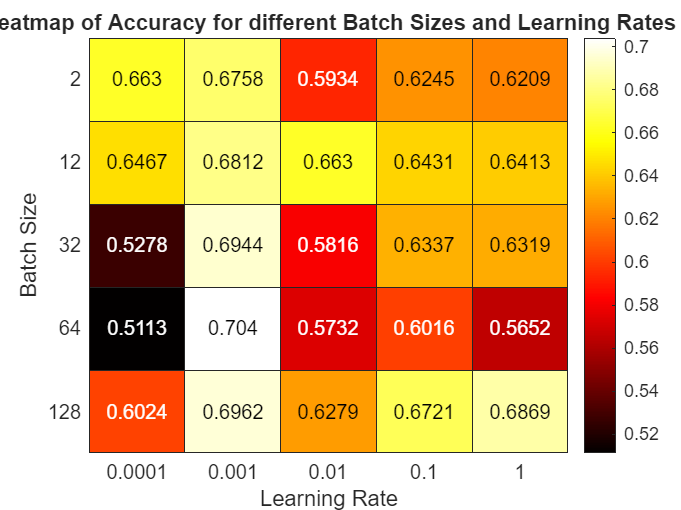

% Step 1: Import data from Excel
filename = 'hparams_table.csv'; % Replace with your file name
data = readtable(filename);

% Step 2: Convert data to a matrix (skip the header row)
data_matrix = table2array(data(2:6, 2:end)); % Skip batch sizes header

% Step 3: Extract batch sizes and learning rates
batch_sizes = data{2:6, 1};              % First column (batch sizes)
learning_rates = data{1,2:6}; % Column headers as strings

% Step 4: Create the heatmap
heatmap(learning_rates, batch_sizes', data_matrix);
colormap("hot");
% Step 5: Add labels and title
xlabel('Learning Rate');
ylabel('Batch Size');
title('Heatmap of Accuracy for different Batch Sizes and Learning Rates');